clear;
file = 'potdng';

%ims = zeros(4, 2000-16, 1500-16, 3, 'single');
ims = zeros(4, 2000-24, 1500-24, 3, 'single');

for x=0:1:3
    deg = num2str(45 * x);
    ims(x+1, :, :, :) = imread(strcat('cut/', file, deg, '.tif'));
end
clear x;
clear deg;

ims = rgb2lin(ims / 255.0);
imsfft = fft(ims, 4, 1) * 0.5;
clear ims;

imsfftmean = squeeze(imsfft(1, :, :, :)) * 0.5; % 0.5 * Diffuse + 0.5 * Perp + 0.5 * Parallel
imsfftcosine = squeeze(abs(imsfft(2, :, :, :))); % 0.5 * (Perp - Parallel)
clear imsfft;

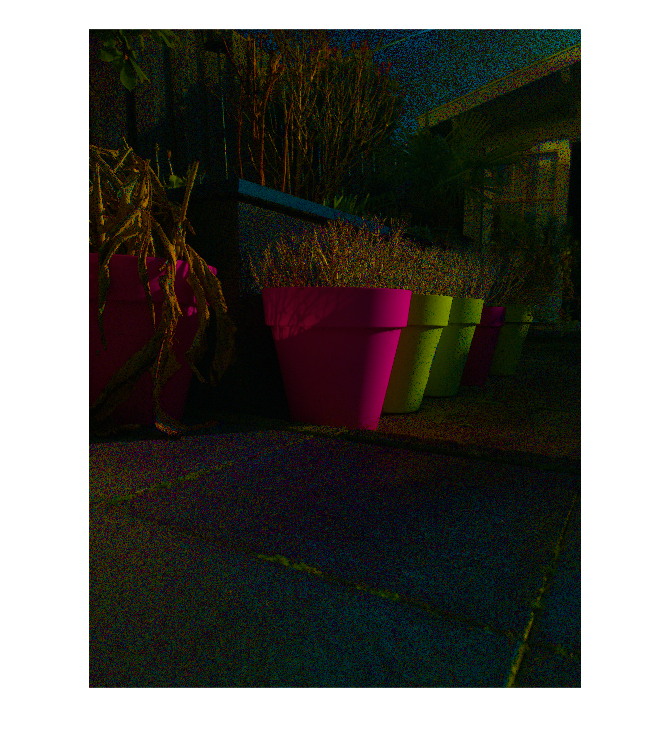

ProjOntoCosineIter = min(imsfftmean ./ max(0.001, imsfftcosine), [], 3);

imshow(lin2rgb(imsfftmean - (ProjOntoCosineIter .* imsfftcosine)));

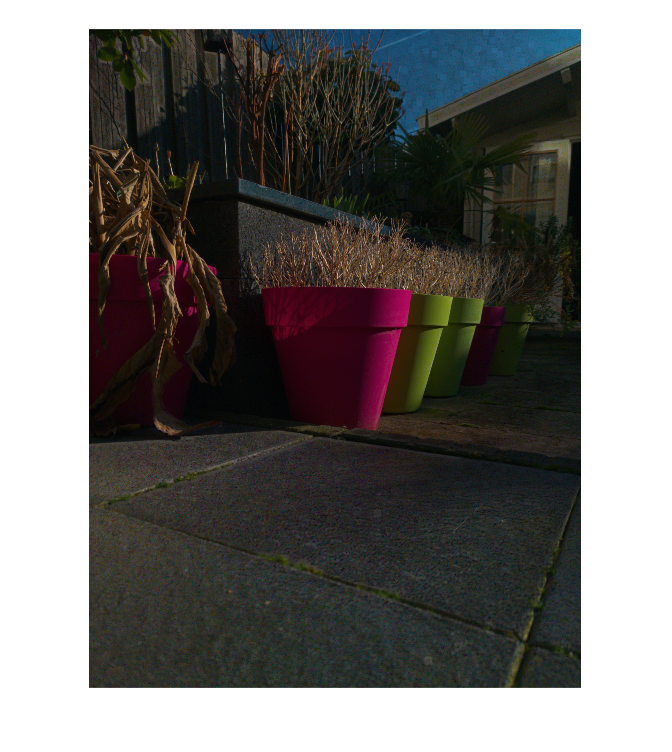


IterCount = 8;
for i = 1:IterCount
    % Left.
    ProjOntoCosineIter(1:end, 1:(end-1)) = min(ProjOntoCosineIter(1:end, 1:(end-1)), ProjOntoCosineIter(1:end, 2:end));

    % Right.
    ProjOntoCosineIter(1:end, 2:end) = min(ProjOntoCosineIter(1:end, 1:(end-1)), ProjOntoCosineIter(1:end, 2:end));

    % Up.
    ProjOntoCosineIter(1:(end-1), 1:end) = min(ProjOntoCosineIter(1:(end-1), 1:end), ProjOntoCosineIter(2:end, 1:end));

    % Down.
    ProjOntoCosineIter(2:end, 1:end) = min(ProjOntoCosineIter(1:(end-1), 1:end), ProjOntoCosineIter(2:end, 1:end));
end

imshow(lin2rgb(imsfftmean - (ProjOntoCosineIter .* imsfftcosine)));

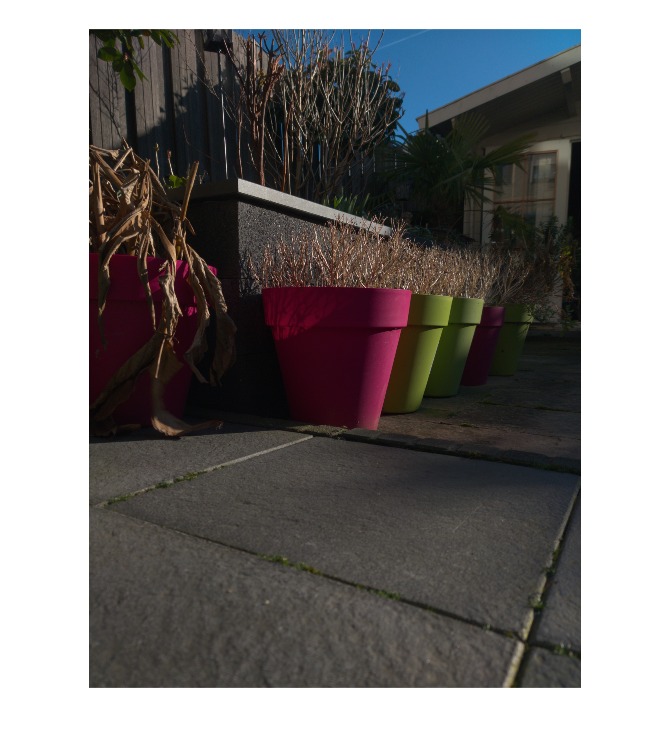

imshow(lin2rgb(imsfftmean));

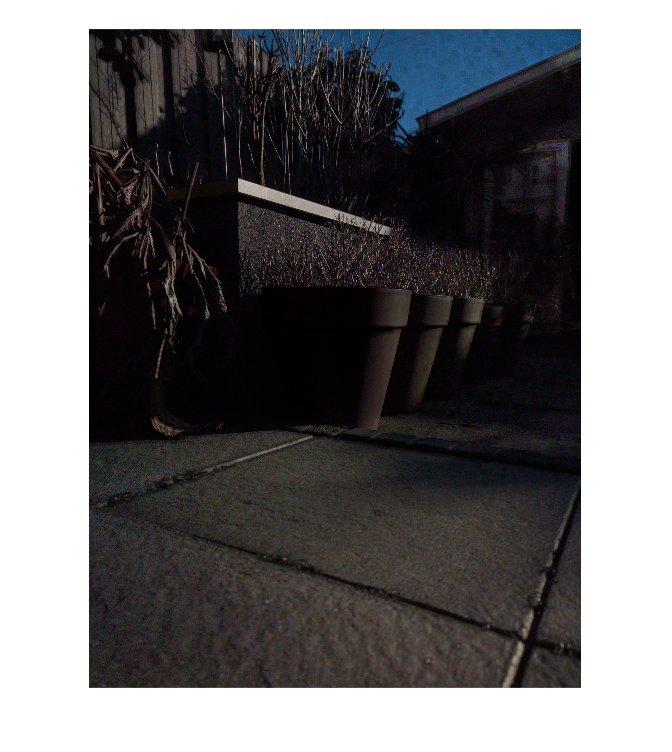

imshow(lin2rgb(ProjOntoCosineIter .* imsfftcosine));